# **Assignment 1- Finite Elements Method 1D**

clc
clear
close all

## **Part 1 **

#### **1.1 Boundary Value Problem (BVP)**

% Symbolic variables
syms E A L g real % Constants
syms x real % Position variable
syms u(x) % Displacement function

% Constants definitions
rho = pi^3/L^2;
s = g*pi^4/L^2;
F = A*E*g*pi^2/L;
r = (x/L)^2;

% Distributed force
q = E*(rho*u-s*r);

% Hooke's law (We don't need to define them as symbolic)
epsilon = diff(u,x);
sigma = E*epsilon;

% Equilibrium
eq1 = diff(sigma,x)+q==0;

% Boundary conditions
cond1 = u(0) == -g; % Displacement 
du_dx_L = diff(u,x);
cond2 = A*E*subs(du_dx_L,x,L) == F; % Force

% General solution 
u_sol = dsolve(eq1, cond1, cond2);
u_sol_simp = vpa(u_sol,4);


**1.2 Exact Solution**

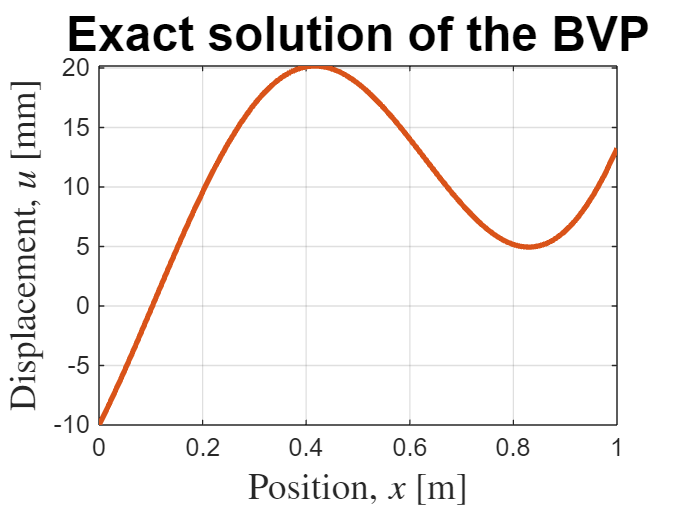

% Apply numeric values
L_val=1;
g_val=0.01;

% Substitute
u_sol_val=(subs(u_sol,[g L], [g_val, L_val]));
u_exact=vpa(u_sol_val,4);

% Plot of the exact solution
figure
colors = lines(8); % Define the colors vector
fplot(u_exact*1000, [0 L_val], 'Color', colors(2,:), 'LineWidth',2) % Converted to millimetres: *1000
xlabel('Position, $x$ [m]', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold')
ylabel('Displacement, $u$ [mm]', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold')
grid on
title('Exact solution of the BVP', 'FontSize', 18, 'FontWeight', 'bold');

**1.3, 1.4, 1.5 Variational Method**

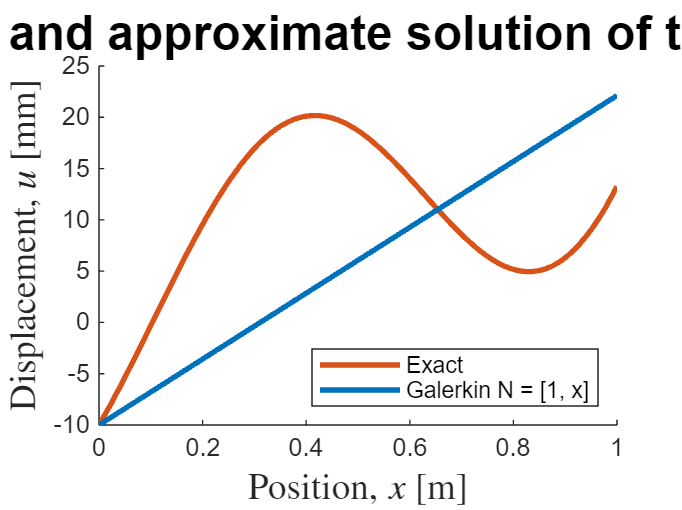

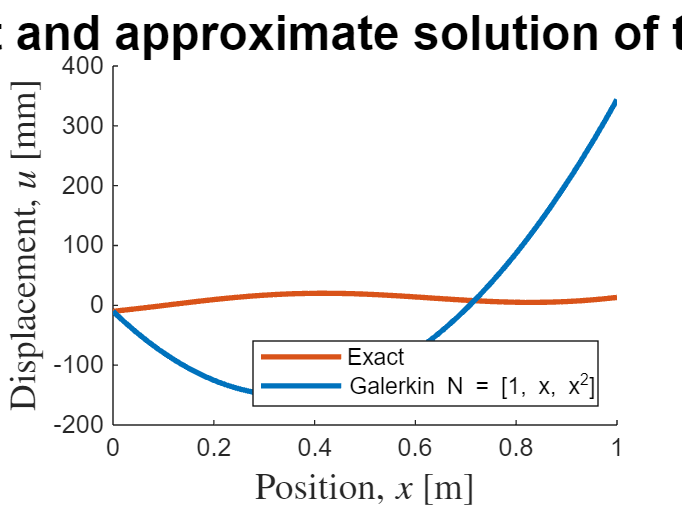

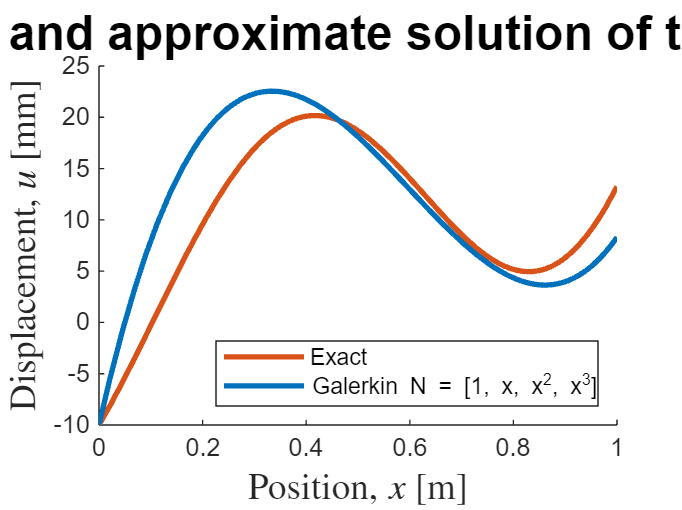

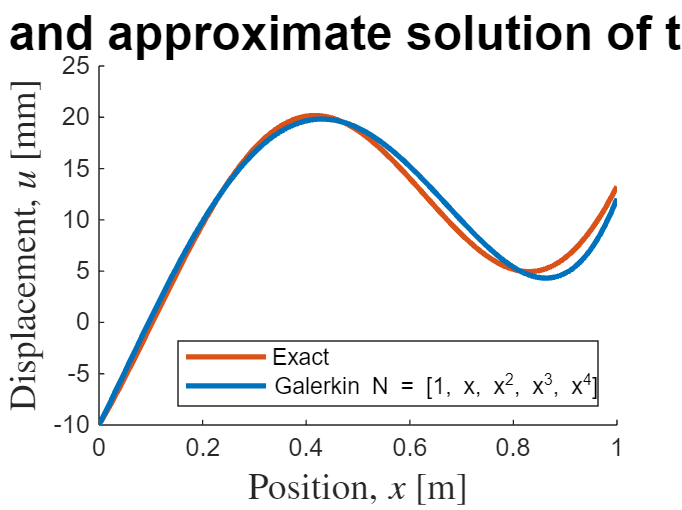

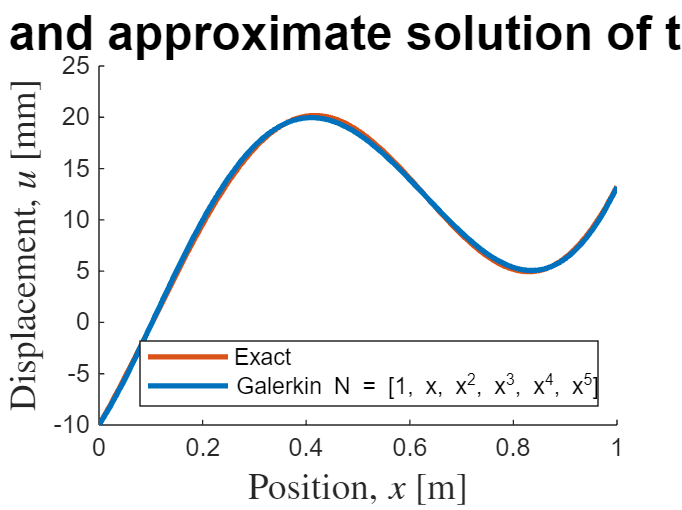

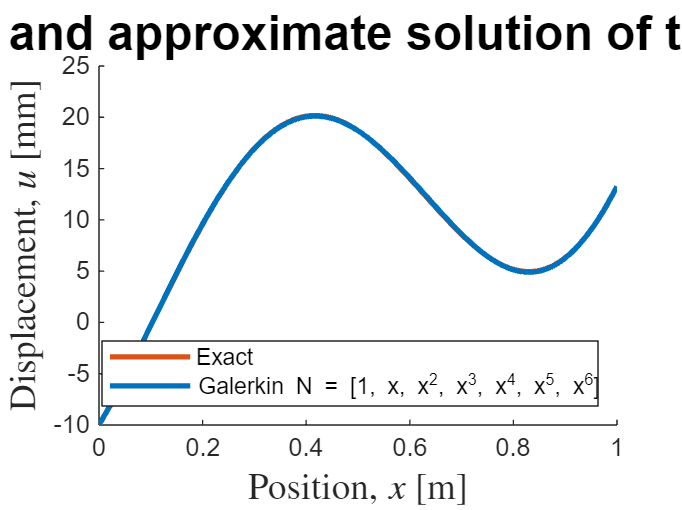

b=g_val*pi^2/L_val; % Boundary conditions
s_val = subs(s,[g L],[g_val L_val]); % Constant
rho_val=subs(rho,L,L_val); % Constant
f = -s_val*x^2/L_val^2; % Source function --> Function in the ODE



% Basis Functions (polynomial functions)

n_end = 6; % Last exponent (x^{n_end})
N = cell(1, n_end); % Inicializar un arreglo de celdas para almacenar cada vector

for i = 1:n_end  % Loop from 1 until n_end 
    N{i} = x.^(0:i);  % Guardar cada vector en una celda de N
end
% N = [1, x, x^2, x^3,x^4, x^5, x^6]; % Basis functions. Resolution functions (3rd order), we have to obtain the amplitudes (constants d)

for i = 1:length(N)
    u_approx{i} = galerkin_solve_Prac1(N{i},f,b,g_val,L_val,rho_val);
    vpa(u_approx{i},4);
    % Plot for every N{i}
    figure(i+1);  
    hold on;
    xlabel('Position, $x$ [m]', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold')
    ylabel('Displacement, $u$ [mm]', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold')
    title('Exact and approximate solution of the BVP', 'FontSize', 18, 'FontWeight', 'bold');
    fplot(u_exact*1000, [0 L_val], 'Color', colors(2,:), 'LineWidth',2) % Converted to millimetres: *1000
    fplot(u_approx{i}*1000, [0 L_val], 'Color', colors(1,:), 'LineWidth',2) % Converted to millimetres: *1000
    legend('Exact', ['Galerkin N = ', char(N{i})],'Location','southeast');
    hold off;
end

**1.6,1.7 Finite linear element basis**

%Discretitzation
x0 = 0; % First node
xF = L_val; % Last node
n_elem = 10; % Number of elements
COOR = linspace(x0,xF,n_elem+1); % Equispaced vector of nodes
CN = zeros(n,2); % Connectivty matrix

Unrecognized function or variable 'n'.

for i=1:n_elem
    CN(i,1) = i;
    CN(i,2) = i+1;
end
